### EE125 Project 4 - Circular Convolution in Matlab / Signal Compression

September 7, 2024

## Part 1: Circular Convolution in Matlab

Reading onscreen.wav and listening to it (and plotting it).

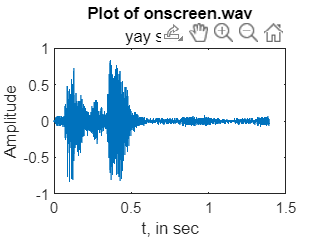

[x, Fs_onscreen] = audioread('onscreen.wav');
% soundsc(x, Fs);
totaltime_onscreen = length(x) ./ Fs_onscreen;
tlin_onscreen = linspace(0, totaltime_onscreen, totaltime_onscreen * Fs_onscreen);
plot(tlin_onscreen, x);
xlabel('t, in sec')
ylabel('Amplitude')
title('Plot of onscreen.wav', 'yay star trek')

Load smallChurch_fs22k.mat then listen and plot h(n).

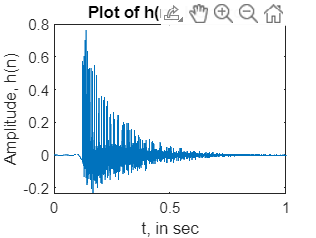

% load('smallChurch_fs22k.mat');
% soundsc(hChurch, Fs_onscreen);
totaltime_hchurch = length(hChurch) ./ Fs_onscreen;
tlin_hchurch = linspace(0, totaltime_hchurch, totaltime_hchurch * Fs_onscreen);
plot(tlin_hchurch, hChurch);
xlabel('t, in sec');
ylabel('Amplitude, h(n)');
title('Plot of h(n), hChurch');

**Question 2 (a) - **In your report, include a plot that zooms in on a portion of h(n) showing some individual reflections. Describe how h(n) changes over time. For example, do the reflections get louder or stronger and why? This question isn’t particularly related to the main DSP content of the project, but hopefully you will find it interesting to look at h(n) — I certainly do!

**Response:** To me, h(n) sounds like a compressed low frequency boom noise with some reverb. It peaks in amplitude at around 0.15 sec. The reflections themselves seem to add an additional high frequency tone to the sound, which appear more dense on the zoomed graph. The lower frequencies are still reflected, albiet they seem to decay much faster, as can be seen by the lines that have greater amplitude but are less dense. As for how the reflections change, in h(n) they get more quiet and weaker, either due to decay in energy from the reflection hitting the church walls, and/or possibly because the reflections are destructively interferring. (Basically, I'm not sure if these are the right words to describe it but I think I hear a low and high pitch harmonic reverb, and there's a lot of noise too?)

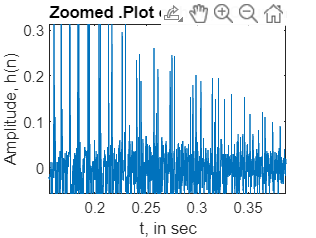

% Zoomed plot for hChurch
plot(tlin_hchurch, hChurch);
xlabel('t, in sec');
ylabel('Amplitude, h(n)');
title('Zoomed .Plot of h(n), hChurch');
xlim([0.155 0.387])
ylim([-0.057 0.313])

Convolve x(n) (onscreen.wav) and h(n) (hChurch) and store in variable.

conv_xh = conv(x, hChurch);
%% This is really cool to listen to. Knowing the result of convolution
%% it makes sense why this happens logically, but I'm still surprised it works.
% soundsc(conv_xh, Fs_onscreen)
% plot(conv_xh);
% xlabel('t, in sec');
% ylabel('Amplitude');
% title('Plot of x(n) * h(n)');

**Question 3 - **Next we want to implement FFT-based convolution. First calculate how much zero-padding you require to have FFT-based circular convolution equal linear convolution. Describe your calculation in your report.

**Response: **The minimum length both vectors must be zero-padded to so that our circular convolution doesn't have time aliasing and equate to linear convolution can be found by: N = L +  M - 1, where L is the length of x(n) and M is the length of h(n). This matches the length of the result from our linear convolution as well, so this result seems to be correct.

N = length(x) + length(hChurch) - 1

N = 52730

**Question 4 - **Now calculate the FFT-based convolution result with and without zero-padding and compare to linear convolution. Note that, even without zero padding to a length that implements linear convolution, you will still need to pad the shorter of h(n) and x(n) so they are of the same length to use FFT-based convolution. Below, we will refer to the latter as the non-zeropadded convolution, even though it still required some padding.

% FFT-based convolution (w/o proper zero padding, only to match length):
% match length of h to x
% Take the DFT of x and h
% convolution in time is multiplication in frequency
% Take the IDFT of the result from multiplication

pad_matchlength = zeros(length(x) - length(hChurch), 1);
hChurch_matchedlength = [hChurch ; pad_matchlength];
eq(length(hChurch_matchedlength), length(x))

ans = logical
   1



% N-point FFT, where N is the length of x, 30681
fft_x = fft(x, length(x));
fft_h = fft(hChurch_matchedlength, length(x));
Yk_matchedlength = fft_x .* fft_h;      % freq domain
yn_matchedlength = ifft(Yk_matchedlength, length(x)); % time domain

% soundsc(x, Fs_onscreen) % original: "on screen" da dit dah
% soundsc(conv_xh, Fs_onscreen) % linconv: reverb, "on screen"
                                %          then da da dit dah dah
                                %          the reverb "double" the beeps
% soundsc(yn_matchedlength, Fs_onscreen)  % non-zero padded:
                                        % While "on screen" is said,
                                        % the da dit dah occurs, still
                                        % "doubled" like in linconv

% FFT-based convolution (proper zero-padding, N = L + M - 1)
% zero pad x and h to length N
% take DFT of x and h
% mult, then IDFT

x_padded = [x; zeros(N - length(x), 1)];
h_padded = [hChurch; zeros(N - length(hChurch), 1)];
eq(length(x_padded), N)

ans = logical
   1


eq(length(h_padded), N)

ans = logical
   1



fft_x_padded = fft(x_padded, N);
fft_h_padded = fft(h_padded, N);

Yk_padded = fft_x_padded .* fft_h_padded;
yn_padded = ifft(Yk_padded, N);

% soundsc(yn_padded, Fs_onscreen); % zero-padded: sounds near identical
                                 % to linconv version

Check the results against linear convolution from earlier and listen to the two outputs. Describe in your report whether you hear any differences, listening especially for the beeping sounds (differences may be quite subtle).

**Answer: **Re-listening to the original "on screen" audio, I made greater detail of the beeps after the "on screen" part is said. It sounds like 3 beeps are made, the middle beep higher in pitch, sort of in a "da dit da" sequence.

The linear convolution result sounded as if there was reverb added to the original audio, and caused the beeps to sound as if they were doubled making it more of a "dah dah dit dah dah".

Interestingly, the non-zero padded (only matched length) result from DFT/IDFT resulted in the beep sequence playing at the same time as "on screen" was being said, instead of after. This is due to time aliasing from the lack of proper zero-padding, causing the end of the signal to alias periodically into the start of the signal. In addition, there seems to be a slight difference in the reverb at the low frequency, where it is less noticable than the linear convolution result.

The properly zero-padded result from the DFT/IDFT resulted in the sound being identical to the linear convolution. I couldn't really notice any difference between the two.

**Question 5 - ** Create and include in your report a figure containing five subplots, which should all have time in seconds on the x axis.

**(a)** A plot of the original signal (signal vs. time)

**(b)** A plot of the output produced by linear convolution (signal vs. time)

**(c)** The numerical difference between the time-based linear convolution output and your zero-padded FFT-based convolution output versus time. If these are of different lengths, your plot should be as long as the shorter of the two. Hint: any differences should be comparable to roundoff error.

**(d)** A plot of the output produced by FFT-based convolution, without zero-padding.

**(e)** The numerical difference between time-based linear convolution and your non-padded FFT-based convolution output versus time. If these are of different lengths, your plot should be as long as the shorter of the two.

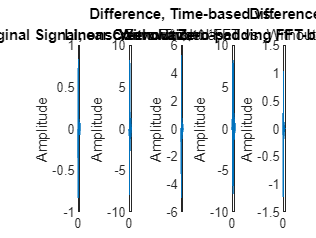

totaltime_linconv = length(conv_xh) ./ Fs_onscreen;
tlin_linconv = linspace(0, totaltime_linconv, totaltime_linconv * Fs_onscreen);

diff_linconv_paddedfft = conv_xh - yn_padded;

totaltime_yn_matchedlength = length(yn_matchedlength) ./ Fs_onscreen;
tlin_matchedlength = linspace(0, totaltime_yn_matchedlength, ...
    totaltime_yn_matchedlength * Fs_onscreen);

conv_xh_shortened = conv_xh(1:(length(yn_matchedlength)));
diff_linconv_nonpadded = conv_xh_shortened - yn_matchedlength;

totaltime_diff = length(diff_linconv_nonpadded) ./ Fs_onscreen;
tlin_diff = linspace(0, totaltime_diff, ...
    totaltime_diff * Fs_onscreen);

subplot(1, 5, 1);
plot(tlin_onscreen, x);
xlabel('t, in sec')
ylabel('Amplitude')
title('Original Signal, onscreen.wav')

subplot(1, 5, 2);
plot(tlin_linconv, conv_xh);
xlabel('t, in sec')
ylabel('Amplitude')
title('Linear Convolution')

subplot(1, 5, 3);
plot(tlin_linconv, diff_linconv_paddedfft);
xlabel('t, in sec')
ylabel('Amplitude')
title('Difference, Time-based vs.', 'Zero Padded FFT')

subplot(1, 5, 4);
plot(tlin_matchedlength, yn_matchedlength);
xlabel('t, in sec')
ylabel('Amplitude')
title('Without Zero-padding FFT-based')

subplot(1, 5, 5);
plot(tlin_diff, diff_linconv_nonpadded);
xlabel('t, in sec')
ylabel('Amplitude')
title('Difference', 'Time-based vs. Without Zero-padding')

**Answer: **Put figure with 5 subplots as an image here as the default render window is very small.

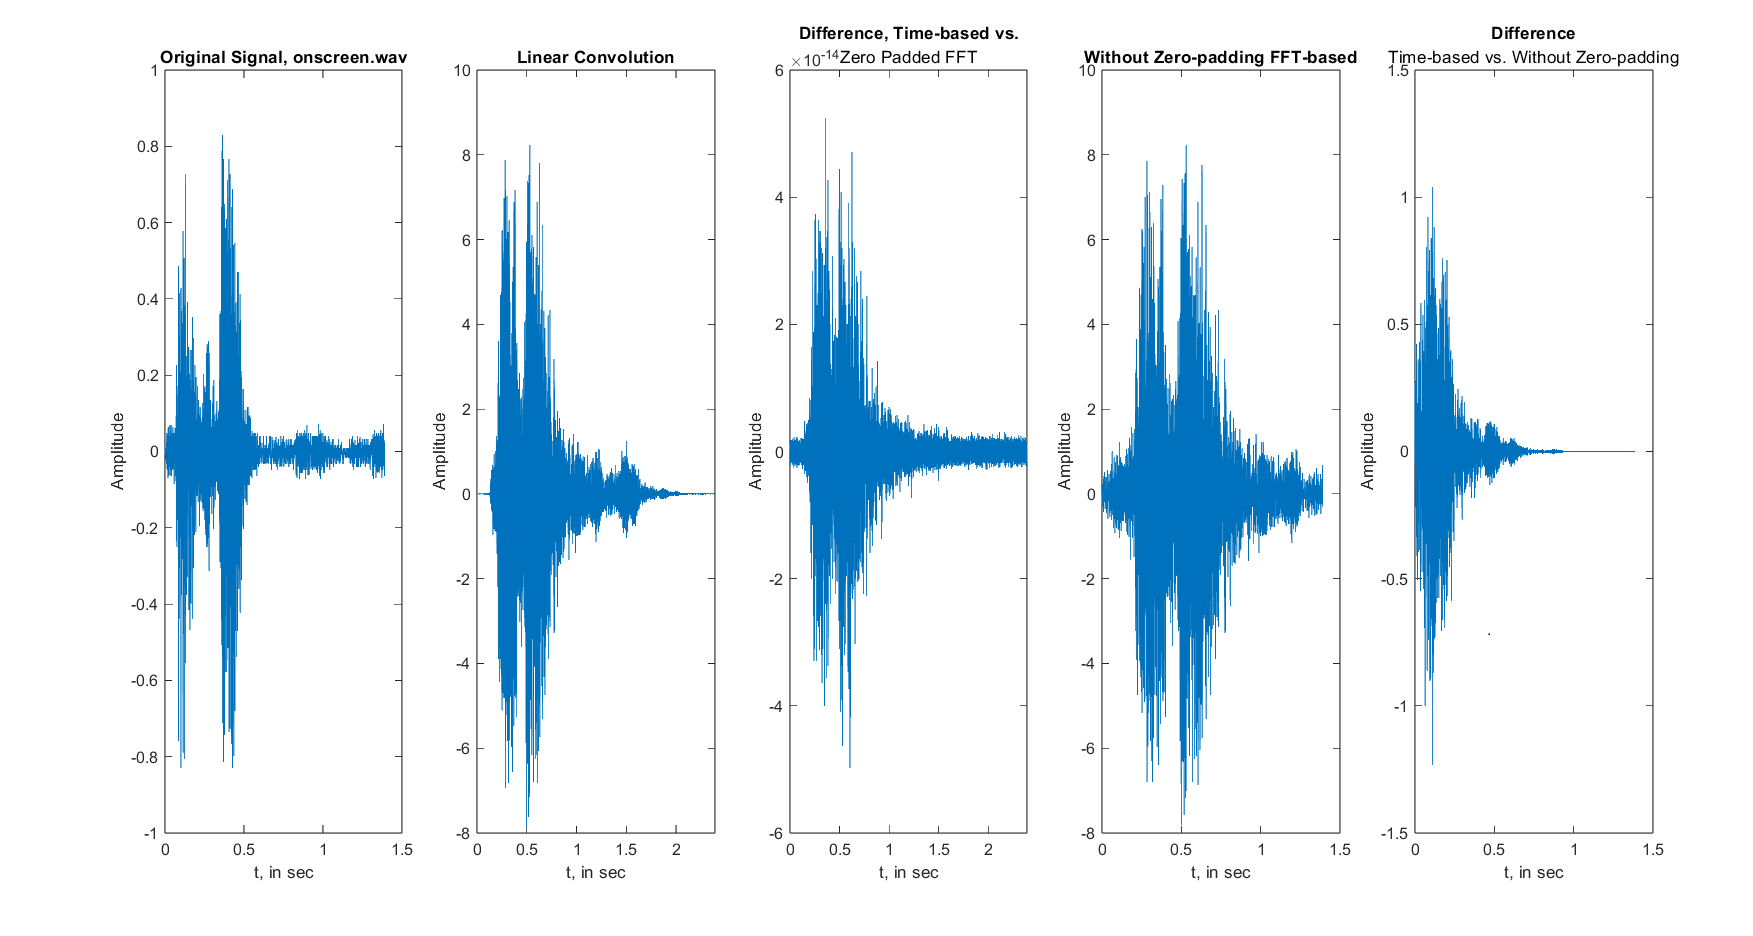

We can see from the first subplot in part **(a)**, that the first two large peaks is the "on screen" speech. The three peaks that follow are likely the beeps described previously as "da dit da".

The second subplot for part **(b)** shows the linear convolution in time of the onscreen and church signals. The overall amplitude is greater which makes sense for convolution, and the effects of the church signal can be seen by the widening of the shape, indicating reverb and greater noise.

Note, in the middle subplot, it is for part **(c)**, the difference between the time-based linear convolution output and the zero-padded FFT-based output. The scale is hard to see, but the y-axis scale for amplitude is at 10^-14, which means any difference is within roundoff error, and thus the signals are practically the same. I'm still surprised by the general structure of the difference, as it follows closely to the shape of both outputs.

As for part **(d),** the fourth subplot, it shows the non-zero padded FFT-based output. We can predict the number of samples that are aliased by calculating the number of samples divided by the sampling rate.

aliasingtime = length(Yk_matchedlength) / Fs_onscreen

aliasingtime = 1.3914

This gives us about 1.4 s, which from the plot can also be visually deduced, where the output abruptly stops at that time. The remaining part of the signal is then time aliasing out output, which can be seen in the fifth subplot for part **(e)**. Interestingly, on a visual inspection it appears as the reverb of the other beeps and final beep of the original.

% soundsc(diff_linconv_nonpadded, Fs_onscreen);

I wanted to investigate a bit futher and listened to the sound, and it does indeed match the output I expected. However, this is a surprising result, as when listening to the non-padded output earlier, I noted that it was the entire beep sequence playing while "on screen" was said. Listening to the output again, I realize that it was only that final aliased beep that played, and the extra beeps I heard during the speech was the reverb. At the tail of the output, there is indeed only two beeps with reverb, and the third beep was again aliased to the beginning. Cool!

*End of part 1! See part2.mlx for the rest of Project 4.*